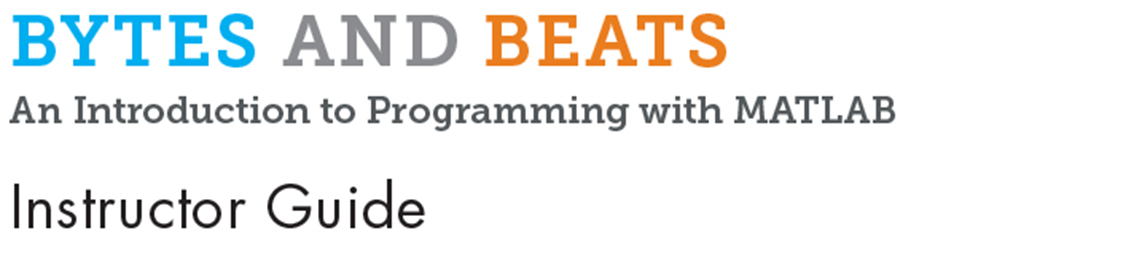

# Module 11: Figures and Callback Functions

**Prerequisite Domain Knowledge:** Functions, Loops, "If" Statements 

**Expected Completion Time: **50 minutes

## Figure Window and Callback Function

*Expected Duration: 30 minutes*

### Learning Objectives

- Understand that the figure window is like a canvas for creating graphics and interactive apps in MATLAB®

- Get a working knowledge of callback functions

### Motivation

In this activity, we will learn to use some building blocks to achieve basic interactivity in a figure window.

### Materials

- MATLAB

### Solution

 
open FigureApp_solution.mlx

### Steps

Tell the students that they will create a musical instrument – a piano/keyboard - by the end of this activity. 

Lets create a musical instrument together

- This first building block for our interactive program will be a figure window. This is like a canvas in MATLAB on which all graphics are created. For example, the plot function they used in the previous activity created the graph in a figure window. The apps that they have been using were all created inside a figure window.

In the MATLAB **Command Window**, type 

 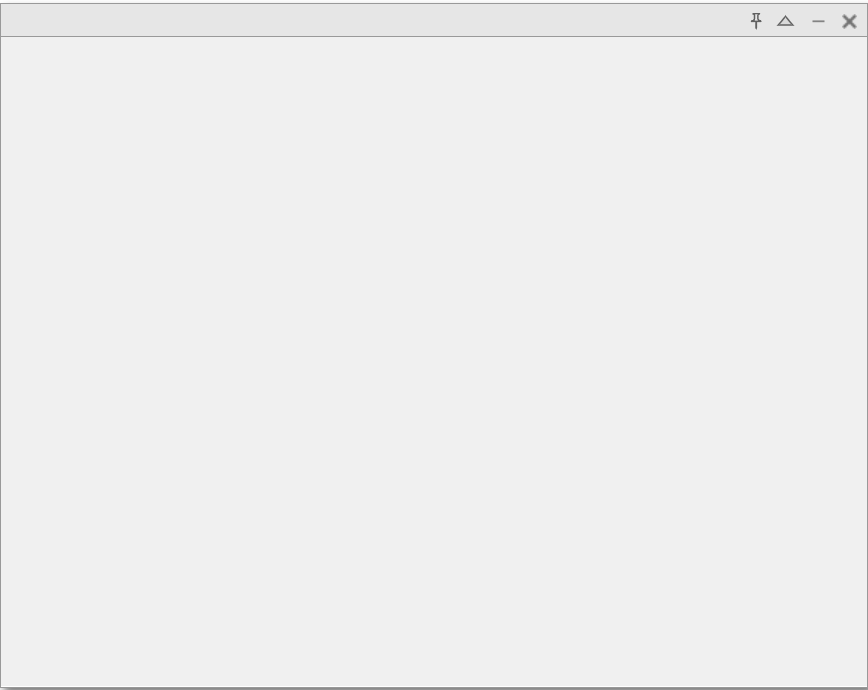 

- This will open a blank figure window. ui`figure` is a function that by default takes in no inputs and outputs a blank figure window for designing apps. But we can optionally give it some inputs. Try:

- This is open a new figure with the name we selected for it.

 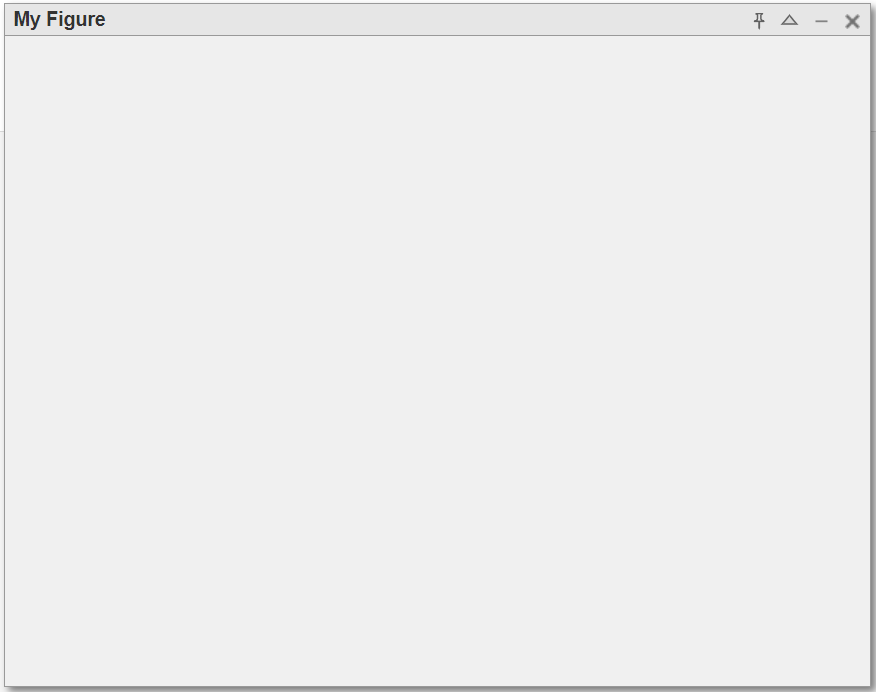

- Just like we set the "Name", we can set many other properties for this figure. For example, we can set its "Color". Show the students by executing this in your **Command Window**:

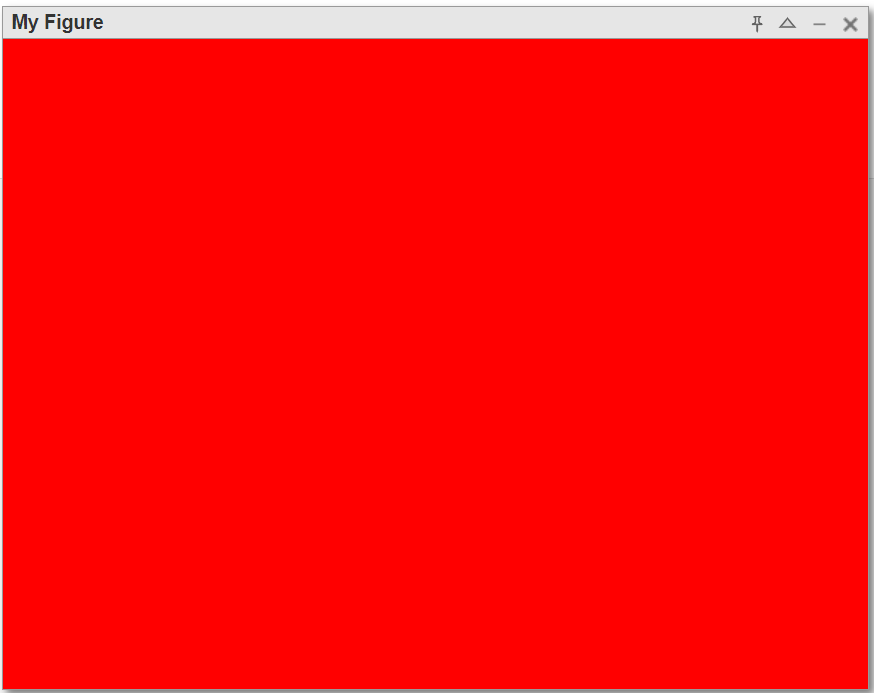

- Tell them to notice here, that you have also assigned an output from the `uifigure. `Tell the students that this will allow us to change the properties of this figure even after we have created it. Show them by executing the following command while the figure is still open:

- Discuss the syntax. We are using the name of the variable followed by a 'dot' followed by the property name. We are using the 'equals' sign to assign this property a new value while the figure is still open.

- Tell the students to open the script "FigureApp.mlx"

 
open FigureApp.mlx

- This script is divided into three sections.

The first section has one line of code. It is creating a figure window and assigning it to a variable called `fig`.

- The students should be able to tell you what kind of figure window is being created – a figure window whose name is “Musical Instrument”. They also see a new property here called "Visible" which is set to "on". This allows the figure window to pop out when we run the live script.

Run this section by clicking the blue bar on the left. A figure window should open. Now discuss with the students if the open figure window is what they expected. 

- ***NOTE-*** Do not close the figure window until instructed to. If a student accidentally closes the figure, re-run the first section.

Along with the opened figure window, the command produced an output which shows some properties of this figure:

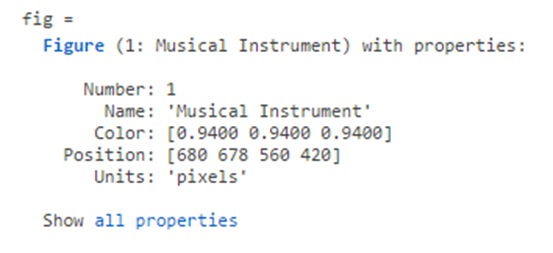

- Tell the students to click on `all properties`. This will display an extensive list of the figure's properties and their values in the **Command Window**. Tell the students not to worry about all of these. We will only be using a few. If they would like to know more about what any of them means, they can click on `Figure `to read the documentation`.`

- For this musical instrument, we are interested in two properties: 

- Tell them to find these in the displayed list (which is in alphabetical order) and see what they are set to. Their value should show empty quotes right now: ' '. 

Tell the students that these properties are "Callback Functions". What this means is that when these properties are set, they should run a function for certain user actions. In other words, this function will be called when a user interacts with the figure in a specific way. For example, every time a user presses a key on the keyboard or releases a key on the keyboard, it will run a function that we define. This is what makes Apps interactive and fun. Let us try a simple example in the next section.

Move to the next section. There is a single line:

- There are two new notations here: the  `.` (dot) and the `@` (at) symbols.

- Let us focus on the left side of the equal sign first. 

- `fig`is the name of the variable that we assigned the figure to. It is also called the *handle* for the figure.

- `KeyPressFcn `is one of the properties of the figure as we saw.

- The dot symbol is used to access a property of the figure as we saw before. The syntax is:

- The`KeyPressFcn `property was empty as we saw earlier. This means that when the figure is in focus, pressing a key on the keyboard should do nothing. Ask the students to click on the figure (to ensure it is in focus) and press any key on the keyboard to verify that nothing is happening. 

To assign a new value to this property, we use the equal sign as always. The right side of the equal sign is the new value that we are giving this property. This must be the name of the function we want to run every time we press a key on the keyboard. But just providing the name of the function is not enough. We want the function to *run* every time a key is pressed. Putting an @ symbol in front of the function name tells MATLAB to ***run*** the function when a user presses a key.

Tell the students to execute this section. Open and click on the figure window, then try pressing any key on the keyboard. You will see an error:

This error says that we have not defined or created a function named `Key_Down `which we told MATLAB to look for. Move to the next section. You will see that this function has been created in the white Text area of the Live Script.

- Tell the students to select the text and click the "Code" button in the "Live Editor" tab. This will convert the text to code.

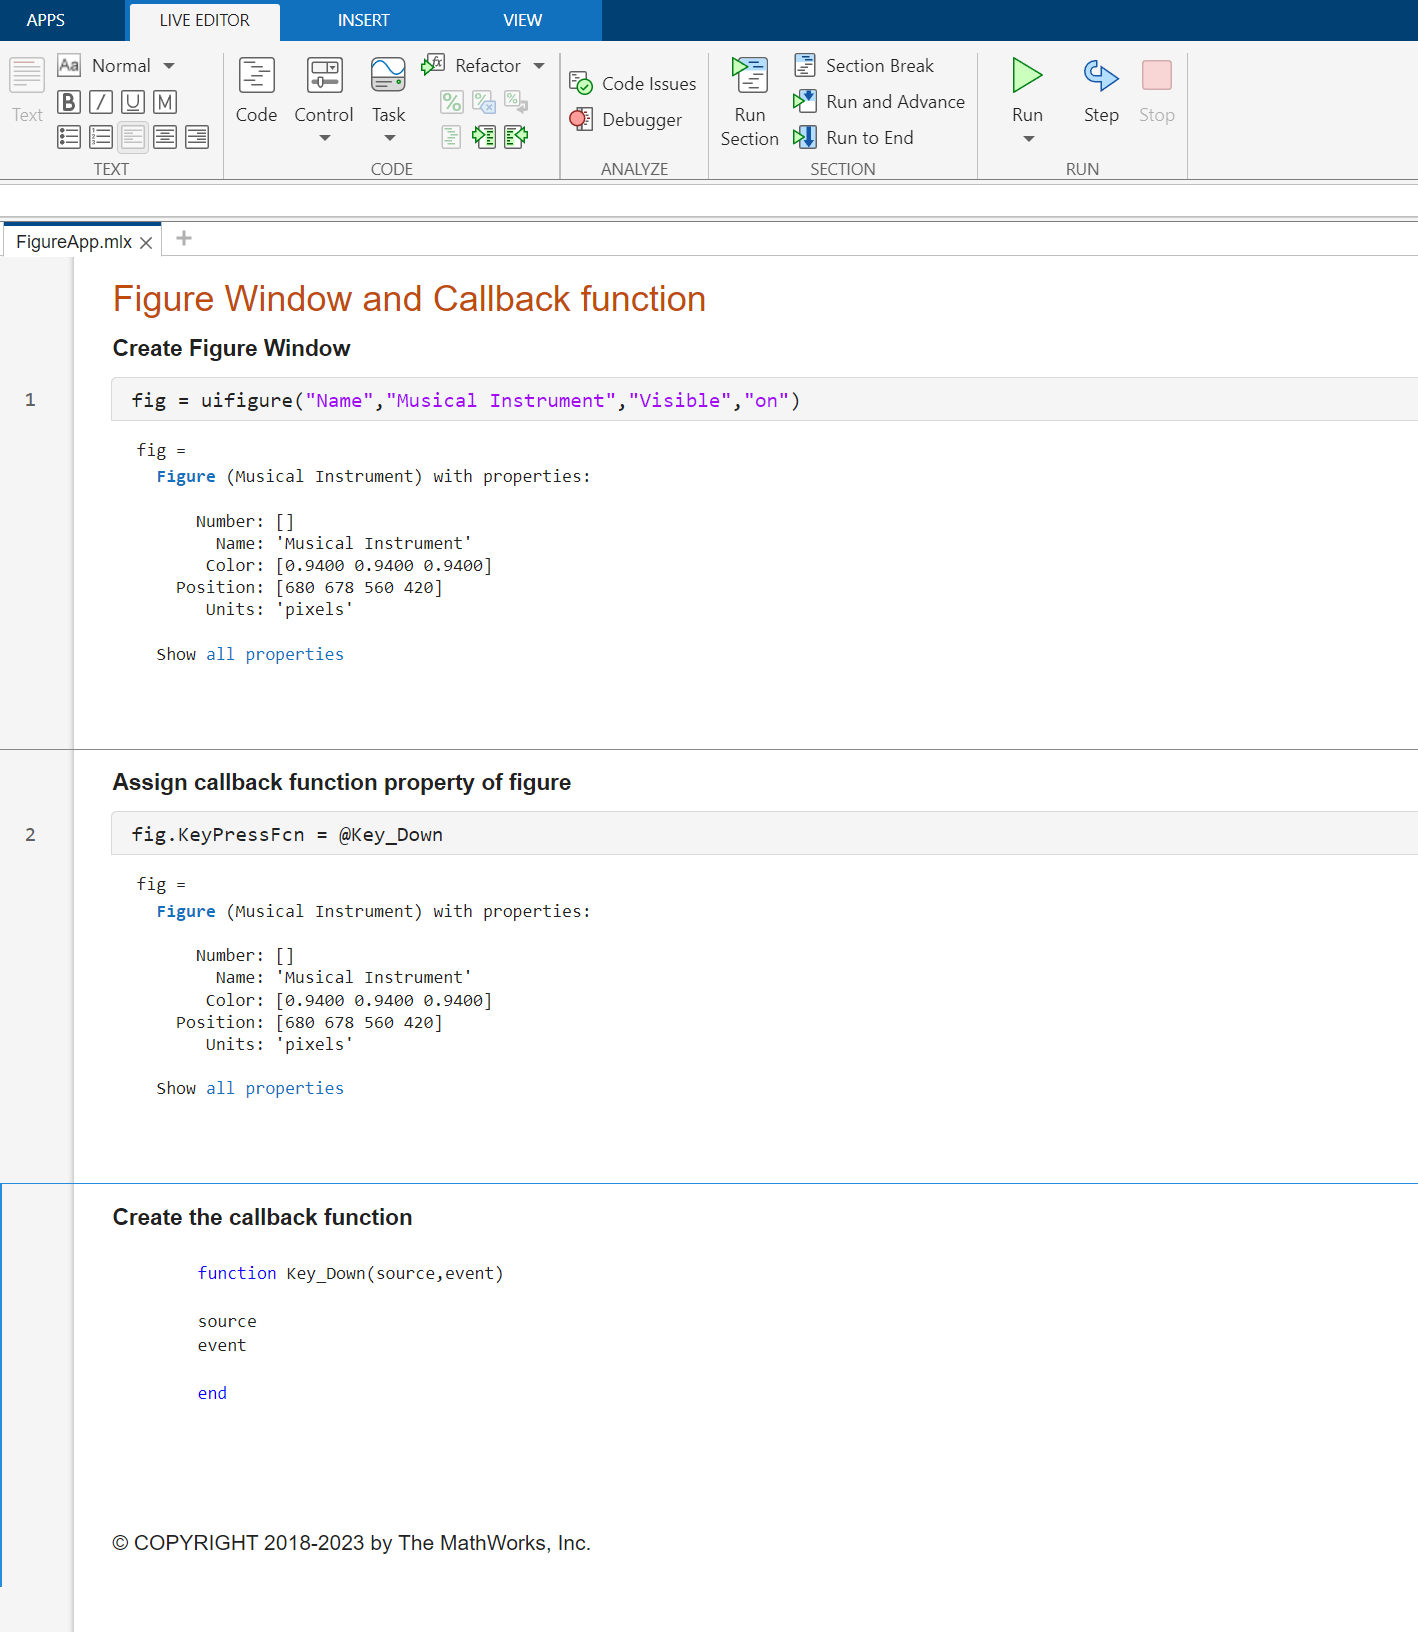

Spend some time discussing what's in the function.

- It has two input arguments. Where do these come from?

- MATLAB automatically sends two inputs to the callback function: `source` and `event`

- These inputs have information about 'who' called the function (figure, in our case) and 'what' event caused it (key press, in our case).

- Inside the function, we just have called the inputs without semi-colons, so that these will be displayed when the function gets called.

Tell the students to close the figure. Run the complete script using the "Run" button in the "Live Editor" tab. 

- Press any key on the keyboard and observe the output in the **Command Window**. 

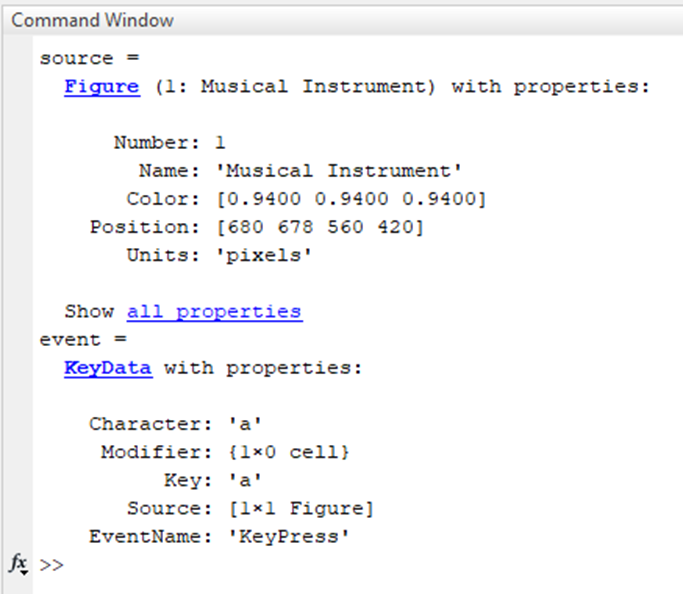

- The source is the figure we have created, and the event has information about what caused the callback, like the name of the key on the keyboard that was pressed.

We can use this input information to do different things inside our callback function based on which key the user pressed. For example, play different tunes for different keys. This is exactly how we will make our instrument.

Students may now try pressing different keys (while keeping the figure window in focus) and keep observing the **Command Window **as they press the keys. The event information should keep updating to show the keys they are pressing. Close the figure when done. Remember that the callback function is a property of the figure. So, we must have the figure in focus when pressing keys.

## Keyboard Piano

*Expected Duration: 20 minutes*

### Learning Objectives

- Combine the use of several basic programming constructs.

- Intuitively understand control flow.

### Motivation

Students will now use the basics of programming they have learned to create their first instrument – the piano.

### Materials

- MATLAB

- Masking Tape (optional)

- Worksheet "Keyboard Piano"

- Handout "Note Frequency"

### Solution

 
open KeyboardPiano_solution.mlx

### Steps

Tell the students to open the Live Script "KeyboardPiano.mlx"

 
open KeyboardPiano.mlx

- This script is like the previous script – it has three sections. 

- The first section creates a figure window with one new additional property called "Interruptible". This allows our callback function to run each time without interruption.

The `Key_Down `function has a line of code to display the Key that was pressed. Let the students run the Live Script and test by pressing different keys with the figure window in focus. Once done, close the figure window.

Ask the students: how would they make a note play when the 'a' key is pressed?

- Use 'if' statement with condition on `event.Key`

Have them follow along with you as you show them how a sine sound of 261.6 Hz can be played for 0.6 s when the key 'a' is pressed. This is what the code should look like:

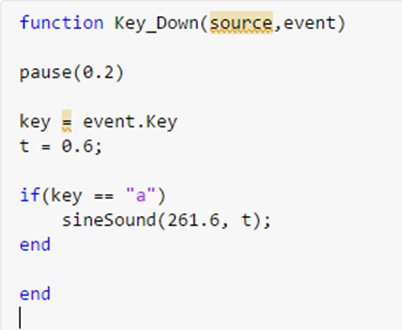

- Remember: it is a good practice to parameterize the code.

Tell them to run the code and test whether the sound plays when the 'a' key is pressed with focus on figure window. Try pressing the key multiple times to get an intuition on how the code control flows.

Now, let us try to change the color of the figure window when the sound is played. `Color`is a property of the figure which is passed as the input `source` in the callback. 

- In MATLAB, a color is specified as a vector with 3 numbers between 0 and 1. The three numbers are for Red, Green and Blue. Students can use the 'Colors' app form their **APPS** tab to find the vector for their favorite colors.

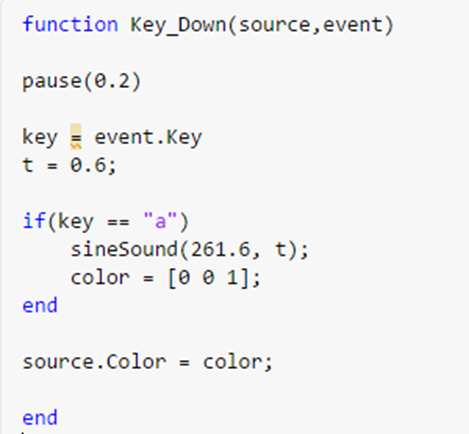

- Execute the script and test by pressing the key 'a'.

At this point, ask the students if they have ideas of what they can do next to play different sounds for different keys. 

- Use `elseif `statements.

The students now have all the tools needed to complete this activity and create their single octave keyboard. They can use the Keyboard Piano Worksheet to fill out the frequencies for this octave in the first table using the Note Frequency Handout. 

Guide them with hints and steps to complete the code, adding seven 'elseif' statements and using their favorite colors for each note. This is what the code in `Key_Down `function should look like:

It is now time to test the piano. Students can run their code and press the keys one by one. To help remember which key corresponds to which note, students can use pieces of masking tape to write the name of the note and cover the keys on the keyboard.

There are many songs that can be played with one octave like "Do Re Mi" or "Jingle Bells". The notes are given at the bottom of the Live Script. Students can find more on the internet and try playing them.

Finally, students can expand this to include more than one octave using other keys of the keyboard. They can also play something other than pure sine tone. They can experiment with the note duration and with playing chords. The possibilities are endless. Spend some time to discuss ideas and if time permits, students can try them.

- **NOTE **–When using MATLAB® Online™, students may sometimes see an error dialog while sound is playing. This is because, too many sounds cannot be played simultaneously on MATLAB Online unlike the Desktop. Make sure that there is a pause statement in the callback function. If the error is frequent, increase the duration of pause slightly.

© COPYRIGHT 2024 by The MathWorks®, Inc.